# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

姓名：   王晨晖         学号：      24307163           专业：      电子信息工程         

## 实验六 模拟原型滤波器及IIR数字滤波器

## 一、实验目的

- 掌握模拟低通滤波器原型的设计方法

- 掌握模拟低通滤波器原型进行频率变换的方法

- 学习MATLAB模拟原型滤波器设计子函数的使用方法

- 掌握模拟滤波器原型进行脉冲响应变换的方法

- 掌握用双线性变换法设计IIR数字滤波器的方法

- 学习MATLAB直接设计IIR模拟滤波器和数字滤波器的方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

1、IIR 数字滤波器间接设计法整体流程

IIR 数字滤波器通常采用间接设计法实现，即先设计满足指标的模拟滤波器，再通过映射方法将其转换为数字滤波器。该方法充分利用了成熟的模拟滤波器设计理论，是工程中最常用的 IIR 滤波器设计方法。完整设计流程如下：

- 输入数字滤波器设计指标（通带 / 阻带截止频率、通带最大衰减\(R_p\)、阻带最小衰减\(A_s\)、采样频率\(F_s\)）

- 将数字频率指标转换为模拟频率指标（脉冲响应不变法采用线性映射，双线性变换法需进行频率预畸变）

- 计算模拟低通滤波器原型的最小阶数N和截止频率\(\Omega_c\)

- 设计模拟低通滤波器原型（本实验使用巴特沃斯和切比雪夫 I 型两种原型）

- 通过模拟域频率变换，将低通原型转换为实际所需的模拟滤波器（低通、高通、带通、带阻）

- 采用脉冲响应不变法或双线性变换法，将模拟滤波器数字化为数字滤波器

- 验证数字滤波器的频率特性是否满足设计要求

2、模拟低通滤波器原型设计

模拟低通滤波器原型是设计其他类型滤波器的基础，本实验主要使用巴特沃斯滤波器和切比雪夫I型滤波器

巴特沃斯滤波器的核心特点是通带和阻带内幅频特性单调下降，在 3dB 截止频率处衰减精确为 3dB。其平方幅度响应为：$\(|H_a(j\Omega)|^2 = \frac{1}{1+\left(\frac{\Omega}{\Omega_c}\right)^{2N}}\)$

切比雪夫 I 型滤波器的核心特点是通带内幅频特性等波纹波动，阻带内单调下降。在相同指标下，切比雪夫 I 型滤波器所需的阶数低于巴特沃斯滤波器，可有效降低系统复杂度。其平方幅度响应为：$\(|H_a(j\Omega)|^2 = \frac{1}{1+\varepsilon^2 C_N^2\left(\frac{\Omega}{\Omega_p}\right)}\)$

3、模拟域频率变换

通过频率变换可将归一化模拟低通原型滤波器转换为任意截止频率的低通、高通、带通、带阻滤波器，变换关系如下：

- 低通→低通：$\(s \to \frac{s}{\Omega_0}\)$，$\(\Omega_0\)$为目标低通滤波器的截止角频率

- 低通→高通：$\(s \to \frac{\Omega_0}{s}\)$，$\(\Omega_0\)$为目标高通滤波器的通带截止角频率

- 低通→带通：$\(s \to \frac{s^2+\Omega_0^2}{sB}\)$，$\(\Omega_0=\sqrt{\Omega_{p1}\Omega_{p2}}\)
$为中心角频率，$\(B=\Omega_{p2}-\Omega_{p1}\)为$通带带宽

- 低通→带阻：$\(s \to \frac{sB}{s^2+\Omega_0^2}\)$，$\(\Omega_0=\sqrt{\Omega_{s1}\Omega_{s2}}\)$为中心角频率，$\(B=\Omega_{s2}-\Omega_{s1}\)$为阻带带宽

4、模拟滤波器数字化方法

（1）脉冲响应不变法

脉冲响应不变法的核心思想是使数字滤波器的单位脉冲响应$\(h(n)\)$等于模拟滤波器单位冲激响应$\(h_a(t)\)$的采样值，即：


$$\(h(n) = h_a(nT)\)$$


其中T为采样周期。其 s 平面到 z 平面的映射关系为$\(z=e^{sT}\)$。

特点：

- 时域特性逼近好，适合对时域波形要求高的场景

- 存在频谱混叠现象，仅适用于带限的低通和带通滤波器，不适用于高通和带阻滤波器

- 模拟频率与数字频率呈线性关系：$\(\omega = \Omega T\)$

（2）双线性变换法

双线性变换法通过非线性频率压缩将整个 s 平面映射到 z 平面的单位圆内，映射关系为：


$$\(s = \frac{2}{T} \cdot \frac{1-z^{-1}}{1+z^{-1}}\)$$


特点：

- 彻底消除了频谱混叠现象，适用于所有类型的滤波器

- 会产生频率非线性畸变，因此需要在设计前对数字频率进行预畸变：$\(\Omega = \frac{2}{T} \tan\left(\frac{\omega}{2}\right)\)$

## 四、实验所用MATLAB函数

（列出实验中需要用到的MATLAB函数并简述其功能）

buttord(wp, ws, Rp, As, 's')：计算巴特沃斯滤波器的最小阶数和截止频率

cheb1ord(wp, ws, Rp, As, 's')：计算切比雪夫 I 型滤波器的最小阶数和截止频率

buttap(N)：设计 N 阶归一化巴特沃斯模拟低通原型

cheb1ap(N, Rp)：设计 N 阶归一化切比雪夫 I 型模拟低通原型

butter(N, Wn, 'ftype', 's')：设计巴特沃斯模拟 / 数字滤波器

cheby1(N, Rp, Wn, 'ftype', 's')：设计切比雪夫 I 型模拟 / 数字滤波器

lp2lp(b, a, W0)：低通→低通模拟滤波器变换

lp2hp(b, a, W0)：低通→高通模拟滤波器变换

lp2bp(b, a, W0, BW)：低通→带通模拟滤波器变换

lp2bs(b, a, W0, BW)：低通→带阻模拟滤波器变换

impinvar(b, a, Fs)：脉冲响应不变法转换模拟滤波器为数字滤波器

bilinear(num, den, Fs)：双线性变换法转换模拟滤波器为数字滤波器

freqs(B, A, w)：计算模拟滤波器的频率响应

freqz(b, a, n, Fs)：计算数字滤波器的频率响应

zplane(b, a)：绘制数字滤波器的零极点分布图

tf2zp(B, A)：将传递函数形式转换为零极点增益形式

poly(p)：将零极点转换为多项式系数

unwrap(phase)：展开相位响应，消除 2π 跳变

## 五、实验内容、方法、代码与结果

### **题目1**：设计一个*模拟低通滤波器*，通带截止频率$f_p=6kHz$，通带最大衰减$R_p\le1dB$，阻带截止频率$f_s=15kHz$，阻带最小衰减$A_s\ge30dB$。要求：

### （1）请用解析法（根据教材上例6.2.1的求解过程）实现巴特沃斯滤波器的设计，并分别用阻带条件求解和通带条件求解Ωc，得到两个模拟滤波器。在一张图同时画出两个滤波器的幅频特性（先除以最大值归一化，再取dB）。观察两个滤波器的3dB截止频率Ωc，并给出结论，那种求解方式的Ωc更大。

### （2）matlab库函数法实现巴特沃斯低通滤波器的设计，绘制幅频特性（归一化取dB）和相频特性曲线、零极点分布图，并列写出传递函数表达式。

**解答1**：

% Insert your code here
%%%%%(1)%%%%
fp = 6000;
fs = 15000;
Ap = 1;
As = 30;
%巴特沃斯
Wp = 2 * pi * fp; % 通带角频率
Ws = 2 * pi * fs; % 阻带角频率
ksp = Ws / Wp; % 频率比
lamdasp = sqrt((10^(As / 10) - 1) / (10^(Ap / 10) - 1)); % 衰减比
N = ceil(abs(log10(lamdasp) / log10(ksp))); % 滤波器阶数
Wcp = 1/Wp * (10^(Ap / 10) - 1)^(1 / (2 * N)); % 通带截止角频率
Wcs = 1/Ws * (10^(As / 10) - 1)^(1 / (2 * N)); % 阻带截止角频率
disp(['巴特沃斯滤波器的阶数N: ', num2str(N)]);

巴特沃斯滤波器的阶数N: 5


disp(['通带截止角频率Wcp: ', num2str(Wcp)]);

通带截止角频率Wcp: 2.3173e-05


disp(['阻带截止角频率Wcs: ', num2str(Wcs)]);

阻带截止角频率Wcs: 2.1168e-05


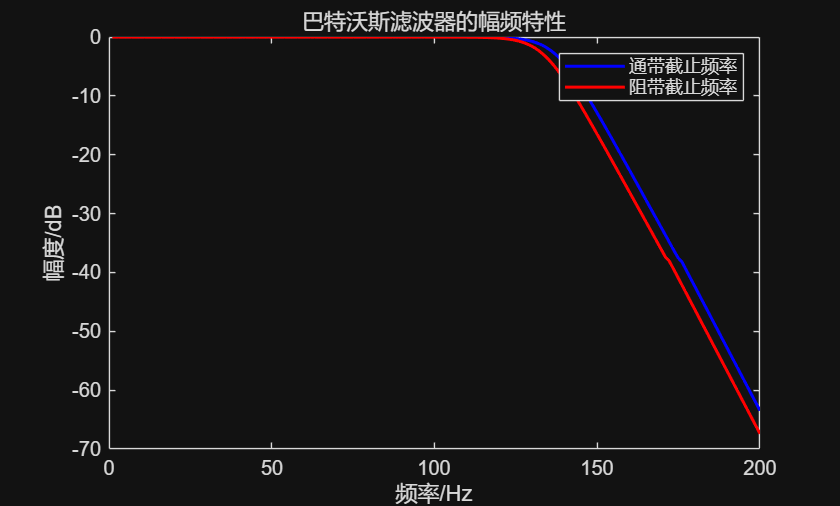

[B1,A1] = butter(N, Wcp, 's'); 
[B2,A2] = butter(N, Wcs, 's');
%归一化幅频特性曲线(dB),0到2pi
figure;
w = linspace(0, 2*pi, 32);
H1 = freqs(B1, A1);
H2 = freqs(B2, A2);
H1 = H1 / max(abs(H1)); % 归一化
H2 = H2 / max(abs(H2)); 
plot(20 * log10(abs(H1)), 'b', 'LineWidth', 1.5);
hold on;
plot(20 * log10(abs(H2)), 'r', 'LineWidth', 1.5);
xlabel('频率/Hz');

ylabel('幅度/dB');
title('巴特沃斯滤波器的幅频特性');
legend('通带截止频率', '阻带截止频率');

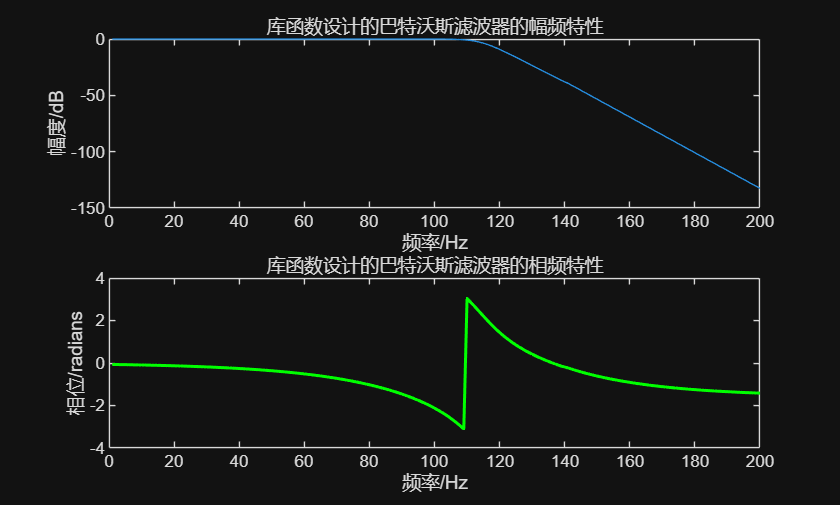


%%%%(2)%%%%
%库函数
[N0, Wn] = buttord(Wp, Ws, Ap, As, 's');
[B0, A0] = butter(N0, Wn, 's');
%归一化幅频特性曲线(dB),0到2pi
figure;
subplot(2,1,1);
H0 = freqs(B0, A0);
H0 = H0 / max(abs(H0)); % 归一化
plot(20 * log10(abs(H0)));
xlabel('频率/Hz');
ylabel('幅度/dB');
title('库函数设计的巴特沃斯滤波器的幅频特性');
subplot(2,1,2);
%相频特性
plot(angle(H0), 'g', 'LineWidth', 1.5);
xlabel('频率/Hz');
ylabel('相位/radians');
title('库函数设计的巴特沃斯滤波器的相频特性');

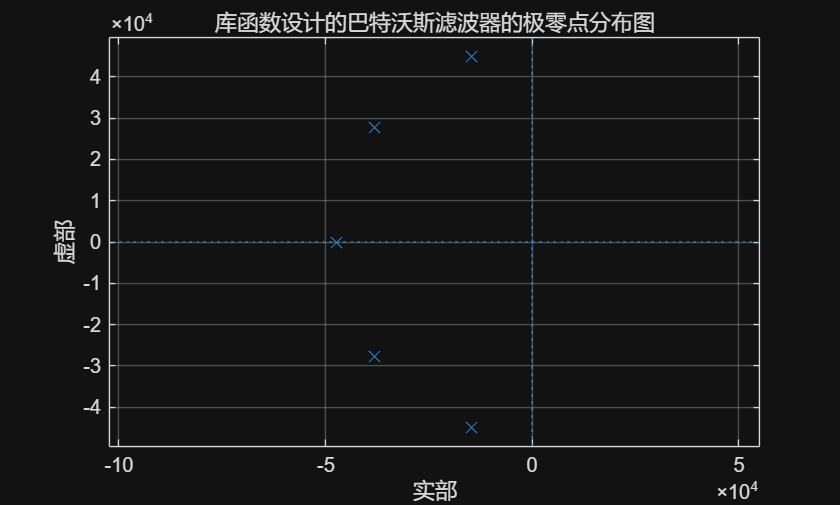

figure;
%极零点分布图
zplane(B0, A0);
title('库函数设计的巴特沃斯滤波器的极零点分布图');
grid on;

%传递函数表达式
syms s;
H_s = poly2sym(B0, s) / poly2sym(A0, s);
disp('库函数设计的巴特沃斯滤波器的传递函数表达式:');

库函数设计的巴特沃斯滤波器的传递函数表达式:


disp(H_s);

$$\frac{235273434844003368435712}{s^{5}+\frac{2626346766485943\,s^{4}}{17179869184}+\frac{3063192960542325\,s^{3}}{262144}+\frac{2208050507164581\,s^{2}}{4}+16116693630047920128\,s+235273434844003301326848}$$


$$H(s) = \frac{2.3527 \times 10^{23}}{s^5 + 1.5287 \times 10^5 s^4 + 1.1685 \times 10^{10} s^3 + 5.5201 \times 10^{14} s^2 + 1.6117 \times 10^{19} s + 2.3527 \times 10^{23}}$$


### **题目2**：用库函数法设计一个*切比雪夫Ⅰ型模拟低通滤波器*，要求通带截止频率$f_p=3.5kHz$，通带最大衰减$R_p\le1dB$，阻带截止频率$f_s=6kHz$，阻带最小衰减$A_s\ge40dB$。绘制归一化的模拟滤波器原型和实际模拟低通滤波器的频率特性。

**解答2**：

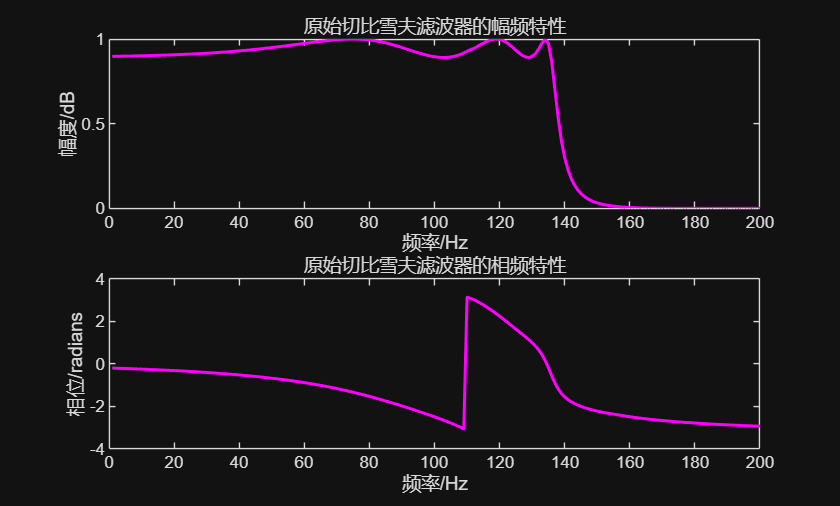

% Insert your code here
fp = 3500;
fs = 6000;
Ap = 1;
As = 40;
%切比雪夫
wp = 2 * pi * fp; % 通带角频率
ws = 2 * pi * fs; % 阻带角频率
[n,wn] = cheb1ord(wp,ws,Ap,As, 's');
[B,A] = cheby1(n,Ap,wn,'s');
figure;%原始
subplot(2,1,1);

H = freqs(B, A);
plot(abs(H), 'm', 'LineWidth', 1.5);
xlabel('频率/Hz');
ylabel('幅度/dB');
title('原始切比雪夫滤波器的幅频特性');
subplot(2,1,2);
plot(angle(H), 'm', 'LineWidth', 1.5);
xlabel('频率/Hz');
ylabel('相位/radians');
title('原始切比雪夫滤波器的相频特性');

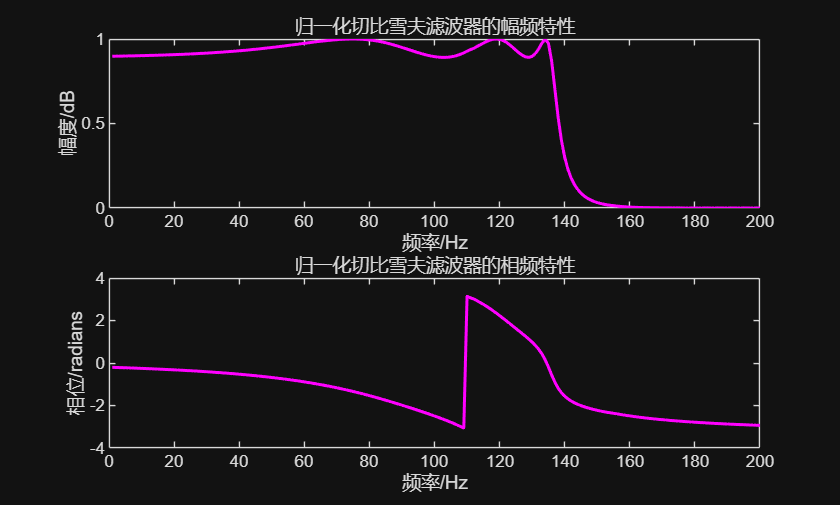

figure;%归一化
subplot(2,1,1);
H = H / max(abs(H)); % 归一化
plot(abs(H), 'm', 'LineWidth', 1.5);
xlabel('频率/Hz');  
ylabel('幅度/dB');
title('归一化切比雪夫滤波器的幅频特性');
subplot(2,1,2);
plot(angle(H), 'm', 'LineWidth', 1.5);
xlabel('频率/Hz');
ylabel('相位/radians');
title('归一化切比雪夫滤波器的相频特性');


% [n,~] = cheb1ord(wp,ws,Ap,As, 's');
% [z,p,k] = cheby1(n,Ap,wn,'s');
% b =  k*real(poly(z));
% a = real(poly(p));
% figure;
% H = freqs(b, a);
% plot(abs(H), 'm', 'LineWidth', 1.5);
% title('切比雪夫滤波器的幅频特性');

### **题目3**：采用*双线性变换法*设计一个巴特沃斯*数字高通滤波器*，要求通带$f_{p}=300Hz,R_p=1dB$；阻带$f_{s1}=150Hz,A_s=20dB$，滤波器采样频率$F_s=1000Hz$。采用解析法求解，按照数字高通——>模拟高通——>模拟低通原型——>设计模拟低通原型——>模拟高通——>数字高通的方法来设计，不要用库函数。

**解答3**：

% Insert your code here
fp = 300;
fs = 150;
Ap = 1;
As = 20;
Fs = 1000; % 采样频率
Rp = Ap;
%双线性变换法
wp = 2*pi*fp/Fs;
ws = 2*pi*fs/Fs;
T = 2;
Omigap = 2/T*tan(wp/2);
Omigas = 2/T*tan(ws/2);
lamdap = 1;
lamdas = Omigap/Omigas;
lamdasp = lamdas/lamdap;
ksp = sqrt((10^(0.1*As)-1)/(10^(0.1*Rp)-1));
N = ceil(log(ksp)/log(lamdasp));
lamdaC = lamdas*(10^(0.1*As)-1)^(-1/2/N);
k=0:N-1;
pk=exp(1j*pi*(0.5+(2*k+1)/2/N));
syms p s z
Gp=prod(1./(p-pk));

Hps = subs(Gp, p, lamdaC/s);


s1 = 2/T * (z-1)/(z+1);
Hz = subs(Hps, s, s1);

% 频率响应
w = linspace(0.01*pi, pi, 800);
z = exp(1j*w);
Hz1 = eval(Hz);

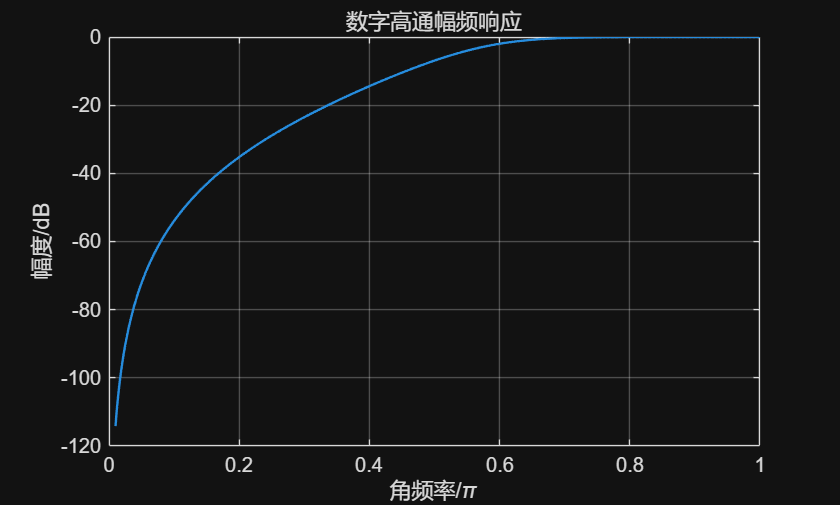

Hz1_dB = 20*log10(abs(Hz1)/max(abs(Hz1)));

figure;
plot(w/pi, Hz1_dB, 'LineWidth', 1.2);
grid on;
xlabel('角频率/\pi');
ylabel('幅度/dB');
title('数字高通幅频响应');

**该数字高通滤波器传递函数为：**$H(z) = \frac{0.1441 - 0.4323 z^{-1} + 0.4323 z^{-2} - 0.1441 z^{-3}}{1 + 0.1726 z^{-1} + 0.3412 z^{-2} + 0.0158 z^{-3}}$

### **题目4**：用*MATLAB库函数法*设计*切比雪夫Ⅰ型数字带阻滤波器*，要求：$f_{p1}=1kHz,f_{p2}=4.5kHz,R_p=1dB$；阻带$f_{s1}=2kHz,f_{s2}=3.5kHz,A_s=20dB$，滤波器采样频率$F_s=10kHz$。请描绘滤波器绝对和相对幅频特性、相频特性、零极点分布图，列出系统传递函数式(程序后已经给出模板)。

**解答4**：

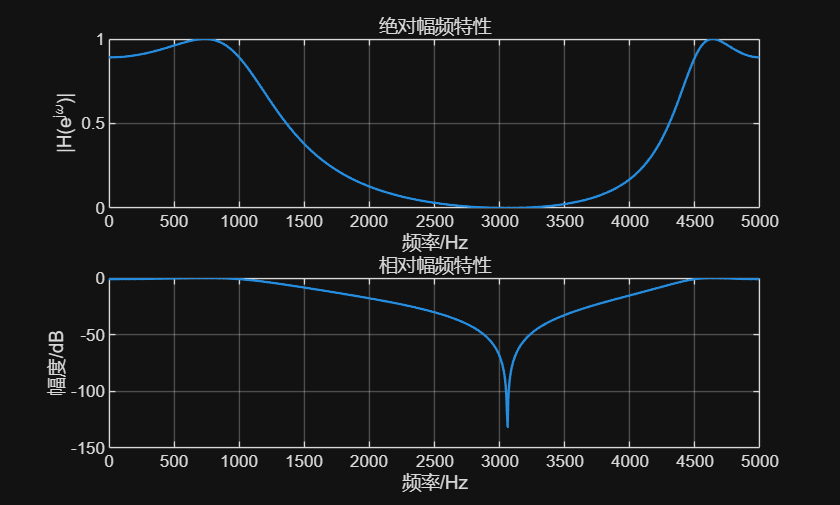

% Insert your code here
fp1 =1000;
fp2 = 4500;
fs1 = 2000;
fs2 = 3500;
Ap = 1;
As = 20;
Fs = 10000;

% 归一化数字频率 (0~1 对应 0~pi)
wp = [fp1 fp2] / (Fs/2);
ws = [fs1 fs2] / (Fs/2);

% 阶数与截止频率
[N, Wn] = cheb1ord(wp, ws, Ap, As);

% 切比雪夫 I 型带阻滤波器
[b, a] = cheby1(N, Ap, Wn, 'stop');

% 频率响应
[H, w] = freqz(b, a, 1024);
f = w / (2*pi) * Fs;

% 绝对幅频特性
figure;
subplot(2,1,1);
plot(f, abs(H), 'LineWidth', 1.2);
grid on;
xlabel('频率/Hz');
ylabel('|H(e^{j\omega})|');
title('绝对幅频特性');

% 相对幅频特性 (dB)
H_dB = 20*log10(abs(H)/max(abs(H)));
subplot(2,1,2);
plot(f, H_dB, 'LineWidth', 1.2);
grid on;
xlabel('频率/Hz');
ylabel('幅度/dB');
title('相对幅频特性');

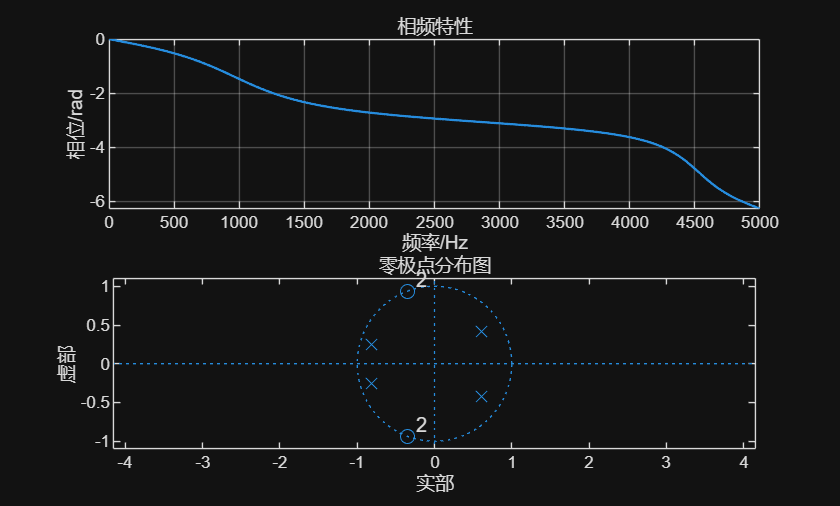


% 相频特性
figure;
subplot(2,1,1);
plot(f, unwrap(angle(H)), 'LineWidth', 1.2);
grid on;
xlabel('频率/Hz');
ylabel('相位/rad');
title('相频特性');

% 零极点分布
subplot(2,1,2);
zplane(b, a);
title('零极点分布图');


% 传递函数
[z, p, k] = tf2zp(b, a);
disp('系统传递函数 H(z) = B(z)/A(z)');

系统传递函数 H(z) = B(z)/A(z)


disp('分子系数 b =');

分子系数 b =


disp(b);

    0.1382    0.1905    0.3421    0.1905    0.1382



disp('分母系数 a =');

分母系数 a =


disp(a);

    1.0000    0.4226   -0.6998    0.0049    0.3939



### **系统传递函数：**$H(z)=\frac{b_0+b_1z^{-1}+b_2z^{-2}+b_3z^{-3}+b_4z^{-4}}{a_0+a_1z^{-1}-a_2z^{-2}+a_3z^{-3}+a_4z^{-4}}$

**计算出本题系统传递函数为：**$H(z) = \frac{0.13823 + 0.19052 z^{-1} + 0.34210 z^{-2} + 0.19052 z^{-3} + 0.13823 z^{-4}}{1 + 0.42262 z^{-1} - 0.69985 z^{-2} + 0.004905 z^{-3} + 0.39387 z^{-4}}$

### **题目5**`：`***采用脉冲响应不变法设计一个巴特沃斯数字带通滤波器******，*****要求：**

### 通带$w_{p1}=0.3\pi ,w_{p2}=0.7\pi ,R_p=1dB;$阻带$w_{s1}=0.1\pi ,w_{s2}=0.9\pi ,A_s=15dB;$滤波器采样频率$F_s=2000Hz$。试显示数字滤波器的幅频特性和零极点分布图，并写出该系统的传递函数。

**解答5**：

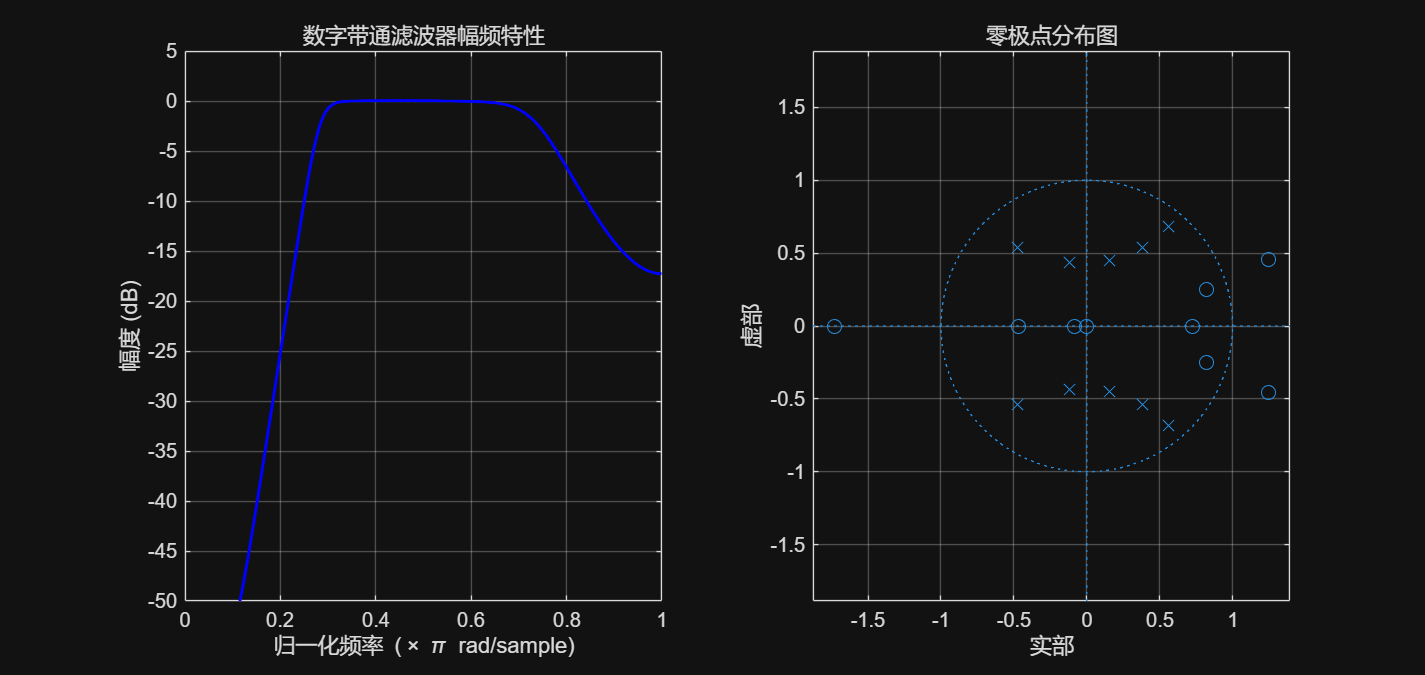

% Insert your code here
wp = [0.3*pi, 0.7*pi];  
ws = [0.1*pi, 0.9*pi];
Rp = 1;
As = 15;
Fs = 2000;
T = 1 / Fs;
Op = wp / T;
Os = ws / T;
[N, Wn] = buttord(Op, Os, Rp, As, 's');
% 设计模拟巴特沃斯滤波器
[B_s, A_s] = butter(N, Wn, 's');
% 模拟滤波器转换数字滤波器，用脉冲响应不变法
[b_z, a_z] = impinvar(B_s, A_s, Fs);
figure('Name', '脉冲响应不变法 - 带通滤波器设计', 'Position', [150, 150, 950, 450]);
% (1) 幅频特性
subplot(1, 2, 1);
[H, w] = freqz(b_z, a_z, 1024);
mag_dB = 20 * log10(abs(H));
plot(w/pi, mag_dB, 'b', 'LineWidth', 1.5); 
hold on;
ylim([-50, 5]);
title('数字带通滤波器幅频特性');
xlabel('归一化频率 (\times \pi rad/sample)');
ylabel('幅度 (dB)');
grid on;
b_z(abs(b_z) < 1e-6) = 0;
% (2) 零极点分布图
subplot(1, 2, 2);
zplane(b_z, a_z);
title('零极点分布图');
grid on;

**传递函数为：**$H(z) = \frac{0.0678 z^{-1} - 0.1747 z^{-2} - 0.0342 z^{-3} + 0.5150 z^{-4} - 0.5251 z^{-5} + 0.0696 z^{-6} + 0.1299 z^{-7} - 0.0419 z^{-8} - 0.0043 z^{-9}}{1 - 1.0114 z^{-1} + 1.2227 z^{-2} - 0.4894 z^{-3} + 0.7180 z^{-4} - 0.3453 z^{-5} + 0.3649 z^{-6} - 0.1065 z^{-7} + 0.0828 z^{-8} - 0.0130 z^{-9} + 0.0081 z^{-10}}$